# Técnicas de procesamiento de señales y datos (MUIE)

## Ejercicio práctico bloque 4.1.4. Efecto del tamaño de la ventana de señal (v3.0)

### Objetivo

El objetivo de este ejercicio es la comprension del impacto del tamaño de ventana de análisis en el espectro calculado de las señales. Disculpad que a veces no aparezcan tildes, pero al cambiar de version de matlab, hay un bug que no permite escribirlas.

### Desarrollo

Se dispone de una señal x(t), sinusoidal de frecuencia 1 Hz y duración variable. Implemente un script en Matlab que realice las siguientes acciones:

- Borre variables, figuras y ventana de comandos:

clear all;
close all force;
clc;

- Tras definir las caracteristicas de x(t), genere a partir de ella una señal discreta x[n] muestreando x(t) a una frecuencia de 10Hz. Defina la longitud (duracion) de la señal x[n] a partir del numero de periodos de quiera considerar (modifique ese valor para evaluar el efecto de usar 3, 6, 9, 12, etc. periodos). Calcule el módulo de la FFT y dibujelo (use 2048 como tamaño de la FFT, y no es necesario que normalice como se ha contado en clase para ver el efecto). Escriba en un comentario breve en el código sus observaciones y justificación, incluyendo un comentario sobre las ventajas e inconvenientes de usar tamaños de ventana grandes o pequeños. 

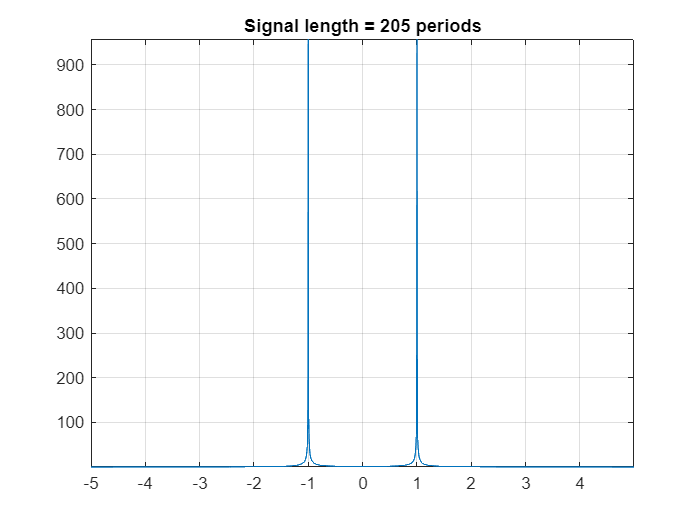

% x(t) signal characteristics
f            = [ 1 ];
amplitude    = [ 1 ];
phase        = [ 0 ];
fs           = 10;

% FFT analysis parameters
fftSize      = 2048;
fftSize_2    = fftSize/2;

% Define the number of periods to use (that will be related to the signal
% duration, which is equal to the window length)
numPeriods   = 205; % Change this value to 3, 6, 9, 12, ...
    
% Generate the signal
timeDuration = numPeriods * 1 / f;
[ x, numSamples, timeIndexes ] = generateSignal(fs, timeDuration, f, amplitude, phase);

% Calculate the fft without normalization (not needed to see the effect)
fftX = fft(x, fftSize); 
plot([fs * (-fftSize_2:(fftSize_2-1)) / fftSize], abs(fftshift(fftX)));
title(['Signal length = ', num2str(numPeriods), ' periods' ]);
%xlim([-fs/2 fs/2]);
grid on
axis tight

% Observaciones y justificación: 
% + Piense y discuta si la forma que observa es coherente con lo visto en teoria 
%   (¿si la señal es sinusoidal, ¿cual deberia ser su espectro?)
% + Piense y discuta la justificacion de la anchura del lobulo principal
% + Piense y discuta lo que sucede cuando se incrementa la duracion de la señal
% + Piense y discuta si podriamos utilizar cualquier numero de periodos 
%   (relacionandolo con el tamaño de la FFT)
% + Piense y discuta las ventajas/inconvenientes de usar ventanas mayores o 
%   menores (no solo en cuanto el analisis, sino en cuanto al coste
%   computacional)
% + Piense y discuta si podemos utilizar ventanas muy largas cuando
%   la señal no es estacionaria

% El espectro de una señal sinusoidal son dos deltas espejadas sobre el "eje
% y", o de amplitudes, concretamente en +f y -f. 

% Debido a la necesidad de enventanar la FFT, es que no podemos concebir
% una delta perfecta en la práctica y es por ello que aparece la función
% tipo sinc. 

% Debido a que la fs es de 10 Hz, la FFT a visualizar será siempre en todas
% las pruebas en un rango de -5 Hz a 5 Hz. 

% En una primer ejecución, tomando dos períodos de señal en simulación,
% aparece una sinc centrada en f = 1 Hz y de gran ancho de base, con 
% cruces por cero en 1.5, 2, 2.5, 3, 3.5 ... así hasta el infinito. 

% Al aumentar la cantidad de periodos a 3, ahora la base se reduce, y los
% cruces por cero suceden en 1.333, 1.666, 2, etc. 

% Al tomar 10 períodos, la sinc se estrecha y los crucen por cero suceden
% en 1.1, 1.2, 1.3, 1.4, etc. 

% Es decir cada cruce por cero sucederá en +- f / numPeriods . Lo cual es
% coincidente con lo visto en la teoría, la transformada de una ventana
% rectangular T tiene lugar a una sinc en frecuencia de crucen por cero en
% multiplos de 1/T. Un fenómeno que se extiende a lo
% largo del tiempo (como lo es el tomar una mayor cantidad de períodos de
% una señal) se estrecha en frecuencia. 

% Al tomar una cantidad de períodos muy grande, 1e6, 1e3, los cruces por
% cero desaparecen, y aparece un pico a la frecuencia de interés que decae
% asintóticamente sobre el eje de frecuencias. 

% Al aumentar numPeriods de a potencias de 2, hasta 128 se observan cruces
% por cero según la tendencia ya descripta, en 256 estos desaparecen.
% Mediante un proceso iterativo, se da con que hasta 204 periodos aparecen
% cruces por cero y de 205 en adelante el decaimiento asintotico. 

% Este valor no es casualidad, es la razón entre el tamaño de la FFT
% seleccionada y la frecuencia de muestreo que se está seleccionando. 
% La cual nos da un valor de 2048 / 10 = 204,8 . Quedando así demostrada de
% manera gráfica la relación entre el tamaño de la FFT, la frecuencia de
% muestreo y el número de períodos que se toman de la señal de interés en
% el tiempo. 

% A partir de tomar 205 períodos, la gráfica deja de estrecharse no por un
% límite físico, sino porque la FFT calculada por MATLAB trunca el valor de
% fftSize a 2048, por más que se tomen numPeriods de 1e6. Esto se visualizó
% en el workspace tomando efectivamente numPeriods de 1e6.

% Si el objetivo fuese acercarse en mayor medida a un delta en la f de
% interés, y no ver un resultado truncado, la única manera no es sólo 
% el aumentar el número de períodos, sino que requiere aumentar el tamaño 
% de la FFT a la par. 
% Aunque esto, requiere de una mayor capacidad de procesamiento y computo 
% por el ordenador utilizado. 

% A su vez, esto aumenta el tiempo de ventana de la señal, si la señal a 
% analizar no es estacionaria, el resultado obtenido será erróneo puesto 
% que la señal cambia más rápido de la que nosotros la podemos grabar. 
% Si aumentamos la cantidad de períodos ganamos en resolución espectral 
% pero se pierde resolución temporal, si la señal no es estacionaria, será
% necesario tomar una ventana temporal lo suficientemente pequeña para que 
% pueda asumirse como constante la señal dentro de ese intervalo de tiempo. 

% Se evidencia entonces, una solución de compromiso entre la resolución
% espectral y el tiempo de computo, las cuales demandarán un correcto ajuste
% de la frecuencia de meustreo, el número de períodos a tomar y el tamaño
% de la FFT a utilizar en función del tipo de señal a medir, de la
% aplicación en particular y de la selección/disponibilidad de la
% tecnología del ordenador a utilizar. 

- Puede mejorar el codigo incluyendo la variacion del tamaño de señal en un bucle y pintando cada espectro en un subplot diferente.

% ...